# Training Unit 2: NEDC Simulation

Fink Lucas / Teichtmeister Marcus, 08.10.2025

## MATLAB Setup

clear
clc

LaTex-Interpreter als Standard für Grafiken setzen

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Schriftgröße für Grafiken setzen

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Verzeichnis wechseln (in Verzeichnis des Live-Skripts)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Loading and processing of existing data

Storing the parameters of the vehicle under investigation

VEHICLE_PARAMETER.VEHICLE_WEIGHT.data        = struct('value', 1250, 'unit', 'kg');
VEHICLE_PARAMETER.E_MOTOR_POWER.data         = struct('value', 66,   'unit', 'kW');
VEHICLE_PARAMETER.BATTERY_CAPACITY.data      = struct('value', 22,   'unit', 'kWh');
VEHICLE_PARAMETER.TRANSMISSION_EFFIENCY.data = struct('value', 96,   'unit', '%');
VEHICLE_PARAMETER.ENGINE_EFFIENCY.data       = struct('value', 94,   'unit', '%');
VEHICLE_PARAMETER.INVERTER_EFFIENCY.data     = struct('value', 97,   'unit', '%');
VEHICLE_PARAMETER.BATTERY_EFFIENCY.data      = struct('value', 90,   'unit', '%');
VEHICLE_PARAMETER.CHARGER_EFFIENCY.data      = struct('value', 94,   'unit', '%');

Next, the collected data "MotorSpeed", "Distance" and "VehicleSpeed" will be read out from the Data.xls File. The data is merged into a table with 3 columns. This is handled by the MATLAB function "importExcelData" which gets the filename as a parameter and returns the extracted data table.

The displayed size of the table is: 2401x3

filename_data = 'Data.xls';
dataTable = importExcelData(filename_data)

dataTable = 2401×3 table
    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]
    _________________    ___________    __________________
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                

Furthermore, a second MATLAB function "importTorqueData" is implemented which stores the torque data in the already existing data table and also includes the sampling time as the first column in the table.

The object **Motor_Torque i**ncludes 2401 data points of motor torque values over time. The dataset provides both the torque data and the corresponding time vector, as well as additional metadata for time, data, and quality. The datapoints of the time vector suggests that the data was recorded with consistent sampling. The metadata also indicates that NaN values are treated as missing data.

filename_torque = 'Torque.mat';
dataTable = importTorqueData(filename_torque, dataTable)

dataTable = 2401×5 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]
    ________________    _________________    ___________    __________________    __________
            0                   0                 0                 0                 0     
          0.5                   0                 0                 0                 0     
            1                   0                 0                 0                 0     
          1.5                   0                 0                 0                 0     
            2                   0                 0                 0                 0     
          2.5                   0                 0                 0                 0     
            3                   0                 0          

The imported torque time series and other artifacts are removed from the workspace.

clearvars -except dataTable VEHICLE_PARAMETER;

### Presenting the results

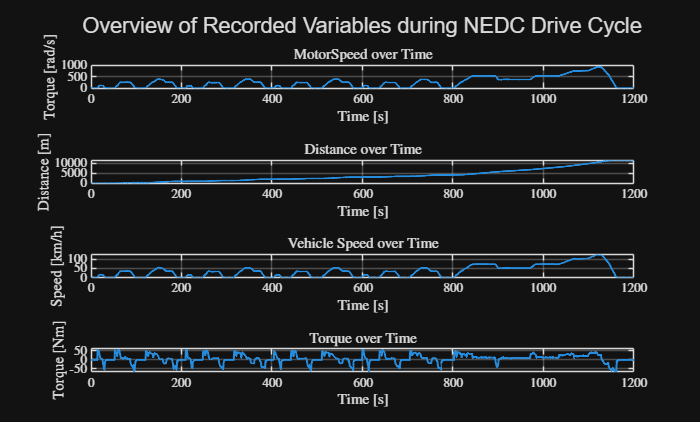

time = dataTable{:,1};              
motor_speed = dataTable{:,2};             
distance = dataTable{:,3};              
vehicle_speed = dataTable{:,4};             
torque = dataTable{:,5};              

figure
tiledlayout(4, 1)    

% 1. Plot: MotorSpeed
nexttile
plot(time, motor_speed, 'LineWidth', 1.2)
grid on
title('MotorSpeed over Time')
xlabel('Time [s]')
ylabel('Torque [rad/s]')

% 2. Plot: Distance
nexttile
plot(time, distance, 'LineWidth', 1.2)
grid on
title('Distance over Time')
xlabel('Time [s]')
ylabel('Distance [m]')

% 3. Plot VehicleSpeed
nexttile
plot(time, vehicle_speed, 'LineWidth', 1.2)
grid on
title('Vehicle Speed over Time')
xlabel('Time [s]')
ylabel('Speed [km/h]')

% 4.Plot: Speed
nexttile
plot(time, torque, 'LineWidth', 1.2)
grid on
title('Torque over Time')
xlabel('Time [s]')
ylabel('Torque [Nm]')

clearvars -except dataTable VEHICLE_PARAMETER;
sgtitle('Overview of Recorded Variables during NEDC Drive Cycle')

Performing Calculations

Motor_RPM = 30/pi .* dataTable.("MotorSpeed[rad/s]")

Motor_RPM =      0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000


dataTable = [dataTable, table(Motor_RPM,VariableNames="MotorSpeed[rpm]")]

dataTable = 2401×6 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]
    ________________    _________________    ___________    __________________    __________    _______________
            0                   0                 0                 0                 0                0       
          0.5                   0                 0                 0                 0                0       
            1                   0                 0                 0                 0                0       
          1.5                   0                 0                 0                 0                0       
            2                   0                 0                 0                 0            

AVG_VELOCITY = 1/dataTable.('sampling_time[s]')(2401) * dataTable.("Distance[m]")(2401) * 3.6

AVG_VELOCITY =     34.1392e+000

P_mech = dataTable.("MotorSpeed[rad/s]") .* dataTable.('Torque[Nm]');
dataTable = [dataTable, table(P_mech, VariableNames="P_mech[W]")]

dataTable = 2401×7 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]    P_mech[W]
    ________________    _________________    ___________    __________________    __________    _______________    _________
            0                   0                 0                 0                 0                0               0    
          0.5                   0                 0                 0                 0                0               0    
            1                   0                 0                 0                 0                0               0    
          1.5                   0                 0                 0                 0                0        

E_inst = 1 / 2 .* dataTable.("P_mech[W]");
dataTable = [dataTable, table(E_inst, VariableNames="E_inst[J]")]

dataTable = 2401×8 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]    P_mech[W]    E_inst[J]
    ________________    _________________    ___________    __________________    __________    _______________    _________    _________
            0                   0                 0                 0                 0                0               0            0    
          0.5                   0                 0                 0                 0                0               0            0    
            1                   0                 0                 0                 0                0               0            0    
          1.5